# Read msgs

% bag_android=rosbag('../../../dataset/191116/analysis/1-2019-11-16-14-35-22_android.bag');
% bag_android=rosbag('../../../dataset/191116/2-2019-11-16-14-52-45-android.bag');
bag_android=rosbag('../../../dataset/191211/prius/2019-12-11-15-38-46.bag');

term=[bag_android.StartTime bag_android.EndTime-10];
% term1=[1573943760.111329 1573943822.538092];

time_extracted=term;
% time_extracted=term1;


sbag_android_imu=select(bag_android,'Time',time_extracted,'Topic','/android/galaxy1/imu');
msgs_android_imu=readMessages(sbag_android_imu);
time_android_imu=sbag_android_imu.MessageList{:,1};
time_android_imu_actual=zeros(length(msgs_android_imu),1);
for i=1:length(msgs_android_imu)
    time_android_imu_actual(i)=msgs_android_imu{i}.Header.Stamp.seconds;
end


## Generate Acceleration ground

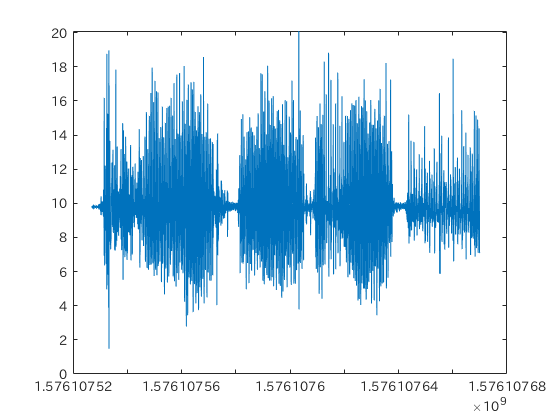

accel_g=generateAccelGround(msgs_android_imu);

plot(time_android_imu_actual,accel_g(:,3));

## High pass filter

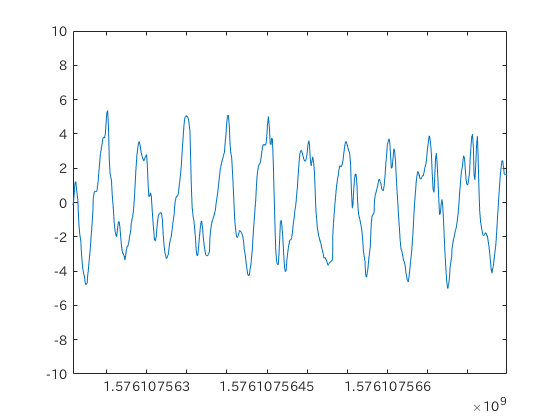

ALPHA=0.90;

accel_g_hpf=accelerationHighPassFilter(accel_g,ALPHA);

plot(time_android_imu_actual,accel_g_hpf(:,3));

## Low pass filter

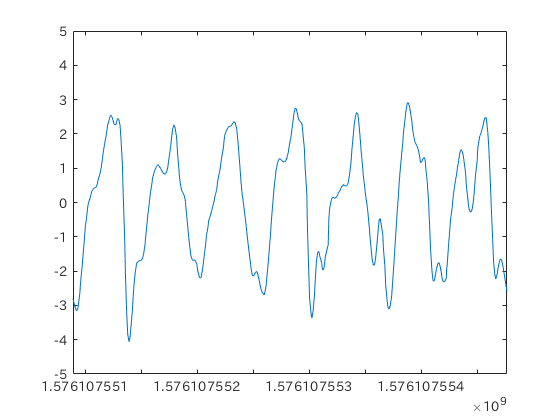

W=7;

accel_g_hpf_lpf=accelerationLowPassFilter(accel_g_hpf,W);

plot(time_android_imu_actual,accel_g_hpf_lpf(:,3));

## Compute P2P

accel_g_filtered=accel_g_hpf_lpf;
[accel_g_lpf_pp,boolean_accel_step,boolean_accel_head]=accelerationPeak2PeakCalculator(accel_g_filtered);

入力引数が不足しています。

エラー: accelerationPeak2PeakCalculator (line 12)
                if accel_g(i,3)-accel_g(j,3)>accel_g_pp_th

time_accel_step=time_android_imu_actual(boolean_accel_step);

plot(time_accel_step,accel_g_lpf_pp(:,3));

accel_g_lpf_pp_4sqrt=nthroot(abs(accel_g_lpf_pp),4);
plot(time_accel_step,accel_g_lpf_pp_4sqrt(:,3))
